% Basic Operator
close all
clearvars

% ==========================================

im = imread('object.jpg');
im = im2double(im);
im = 1 - im;
imshow(im)

% Dilation
SE = strel('disk', 5);
Idil = imdilate(im, SE); imshow(Idil), title('Dilation')

% Erosion
SE2 = strel('disk',5);
Iers = imerode(im , SE2); imshow(Iers), title('Erosion')

% closing
SE3 = strel('disk',5);
Iclos = imclose(im, SE3); imshowpair(Iclos, im), title('closing')

% Opening
SE4 = strel('square', 5);
Iopn = imopen(im, SE4); imshowpair(Iopn, im, 'montage'), title('opening')

% Denoising
close all
clearvars
% =======================================

im = imread('cygnus.tif');
im = im2double(im);
imshow(im)

SE = strel('disk', 5);
I = imopen(im, SE);
I = imclose(I, SE); 
imshow(I), title('De-Noise')

close all
clearvars
% ====================================================

im = imread('rice.tif');
im = im2double(im);

imshow(im)

Im = im;

Th = graythresh(Im);

Im(Im(:, :) < Th) = 0;
Im(Im(:, :) >= Th) = 1;

imshow(Im), title('Threshoulded Image')
imshowpair(Im, im, 'montage')

SE = strel('disk', 40);
I2 = imopen(im, SE); 
imshow(I2)

I3 = im - I2;
imshowpair(im, I3, 'montage')

Th = graythresh(I3);

I3(I3(:, :) < Th) = 0;
I3(I3(:, :) >= Th) = 1;

imshowpair(I3, Im, 'montage')

% Gradiant
close all
clearvars
% ==============================
im = imread('brain.tif');
im = im2double(im);
imshow(im)

se = strel('disk', 3);
I = imdilate(im, se);
I2 = imerode(im, se);

Bound = I - I2; imshowpair(im, Bound, 'Montage')

% __________ Segmentation __________
close all
clearvars

% ====================================================

im = imread('blobs.tif');
im = im2double(im);
imshow(im)

se = strel('disk', 28);
I1 = imclose(im, se); imshow(I1)

se1 = strel('disk', 60);
I2 = imopen(I1, se1); imshow(I2)

se3 = strel('disk', 3);
I3 = imdilate(I2, se3) - imerode(I2, se3); imshow(I3)

imshow(I3 + im)

% _____ Extract Border ______
close all
clearvars
% ===============================================
 im= imread('border.jpg');
 im = rgb2gray(im);
 im = im2double(im);
 
imshow(im)

I = im;
I(2:end-2, 2:end-2) = 0; imshow(I)

se = strel('square', 3);
I = imdilate(I, se);

Rec = imreconstruct(I, im); imshow(Rec)

I2 = im - Rec; imshow(I2)

SE = strel('line', 51, 90);
I3 = imerode(I2, SE);
imshow(I3)

Rec2 = imreconstruct(I3, I2); imshow(Rec2)
imshowpair(I3, Rec2, 'montage')

% Filling holes

Img = I2; imshow(Img)

% Negative
neg = 1 - Img; imshow(neg)

% Erosion
 se = strel('disk', 12);
erd = imerode(neg, se); imshow(erd)

REC = imreconstruct(erd, neg); imshow(1 - REC)

new = imfill(I2, 'holes'); imshow(new)

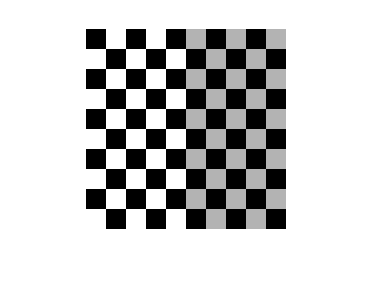

% _______ PSF & deconv _______
close all
clearvars

% ================================================

im = checkerboard(20, 5, 5);
% im = rgb2gray(imread('sat.tif'));
% im = im2double(im);
imshow(im)

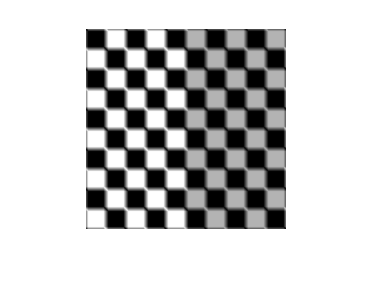


PSF = fspecial('motion', 7, -45);
Deg = imfilter(im, PSF, 'circular');
De = imnoise(Deg,'gaussian',0,1e-6);
imshow(Deg)